% Solving Example 3.2 from Murray's lectures

% Assume values to solve the example
n = 1;
a = 3; b=1; c=1.0; t0=0; tf=6; dt = 0.1;
qu = 1.0;
qx = 0.0;

ft = @(t,x,u) a*x + b*u;

options = odeset('RelTol',1e-13,'AbsTol',1e-300);
time = t0:dt:tf;
P0 = c;

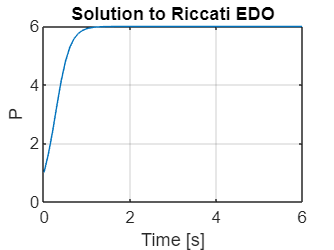

[t, P] = ode23s(@(t,P) riccati(t,P,a,b,qu,qx,n), time, P0, options);
figure(1);
plot(time,P, 'DisplayName','P');
title('Solution to Riccati EDO')
xlabel("Time [s]")
ylabel("P")
grid on;

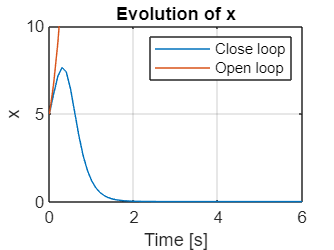

%Runge-Kutta 4
k1 = @(t,x,u) (  ft(t,x,u) );
k2 = @(t,x,u) ( ft(t,x + k1(t,x,u)*dt/2,u) );
k3 = @(t,x,u) ( ft(t,x + k2(t,x,u)*dt/2,u) );
k4 = @(t,x,u) ( ft(t,x + k1(t,x,u)*dt,u) );
f_ud = @(t,x,u) ( x + (dt/6) * ( k1(t,x,u) + 2*k2(t,x,u) + 2*k3(t,x,u) + k4(t,x,u)  )   );

x0 = 5.0;
xOL = zeros(n,length(time));
xOL(:,1) = x0;
xCL = zeros(n,length(time));
xCL(:,1) = x0;
u = zeros(n,length(time));

for i=1:length(time)-1    
    u(:,i) = -(qu\b')*reshape(P(i,:),n,n)*xCL(:,i);
    xCL(:,i+1) = f_ud(time(i),xCL(:,i),u(:,i));
    xOL(:,i+1) = f_ud(time(i),xOL(:,i),0);
end

figure(2);
plot(time,xCL, 'DisplayName','Close loop');
hold on;
plot(time,xOL, 'DisplayName','Open loop');
title('Evolution of x')
xlabel("Time [s]")
ylabel("x")
ylim([0 10]);
legend();
grid on;

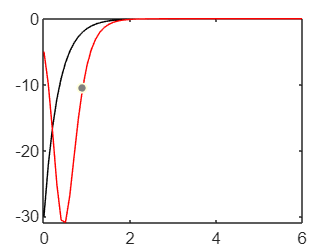

u_opt = @(t,x0) -( 2*a*b*c*exp( a*(2*tf-t0-t) )*x0 ) / ( 2*a-b^2*c*(1-exp(2*a*(tf-t0))) );
figure(3);
plot(time,u_opt(time,x0),"k")
hold on;
plot(time,u,"r")

function dPdt=riccati(~,P,A,B,Qu,Qx,n)
    P = reshape(P,n,n);
    dPdt = P*A + A'*P - P*B*(Qu\B')*P + Qx;
    dPdt = reshape(dPdt,n*n,1);
end

function dxdt = dynamicSys(~,x,A,B,u,n)
    x = reshape(x,n,n);
    dxdt = A*x + B*u;
    dxdt = reshape(dxdt,n*n,1);
end


